# **RS-HL-11: Multi User Simulation**

**UT Austin Oden Institute**

**Hongseok Kim**

**07/12/2024**

## I. Scope

  In this report, the multi user simulation of satellite network control system is presented.

## II. Algorithm 

## III. Code

### III.1 Load the SAT-to-SAT dataset

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

### III.2 Run MDP

% Parameter Setting
time_index_vector = 100:120;
destination_state = 38;

% Run MDP
MDP = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_state);

simulation set up complete! 
Policy: 1 -> Value Iteration: 485
Policy: 2 -> Value Iteration: 15
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 8
Policy: 6 -> Value Iteration: 10
Policy: 7 -> Value Iteration: 9
Policy: 8 -> Value Iteration: 1
Policy: 9 -> Value Iteration: 1
Policy: 10 -> Value Iteration: 1
Policy: 11 -> Value Iteration: 1


### III.3 User 1 Simulation

start_time = 100;
start_state = 3;

% Run Simulation
[time_list, reward_list, state_list, state_value_list]= simulation_test(start_time,start_state,MDP,time_index_vector,destination_state);

simultion_result = [time_list, state_list, reward_list, state_value_list]

simultion_result =   100.0000    3.0000         0    2.0000
  101.0000    4.0000   -1.0000   10.5000
  102.0000    5.0000   -2.0000   19.0000
  103.0000   31.0000  -17.0000   41.5000
  104.0000   32.0000  -18.0000   50.0000
  105.0000   33.0000  -19.0000   58.5000
  106.0000   34.0000  -20.0000   67.0000
  107.0000   35.0000  -21.0000   75.5000
  108.0000   36.0000  -22.0000   84.0000
  109.0000   37.0000  -23.0000   92.5000


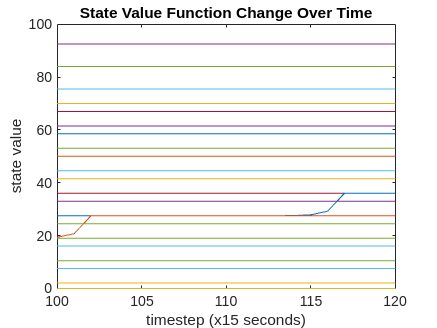

number_of_states = length(sat_to_sat_contact_3d_matrix(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')

### III.4 Modification of sat-to-sat contact matrix from simulation 1

A = sat_to_sat_contact_3d_matrix;

for index = 1:length(time_list)-1

    time_index = time_list(index);
    state_index = state_list(index);

    A(state_index,:,time_index) = 0;
    A(:,state_index,time_index) = 0;
    A(state_index,state_index,time_index) = 1;

end

time_index_vector = 100:120;
destination_state = 38;

% Run MDP
MDP = runMDP(A, time_index_vector,destination_state);

simulation set up complete! 
Policy: 1 -> Value Iteration: 485
Policy: 2 -> Value Iteration: 15
Policy: 3 -> Value Iteration: 5
Policy: 4 -> Value Iteration: 5
Policy: 5 -> Value Iteration: 8
Policy: 6 -> Value Iteration: 10
Policy: 7 -> Value Iteration: 9
Policy: 8 -> Value Iteration: 1
Policy: 9 -> Value Iteration: 1
Policy: 10 -> Value Iteration: 1
Policy: 11 -> Value Iteration: 1


## III.Analysis

### III.1 State Value changing over time

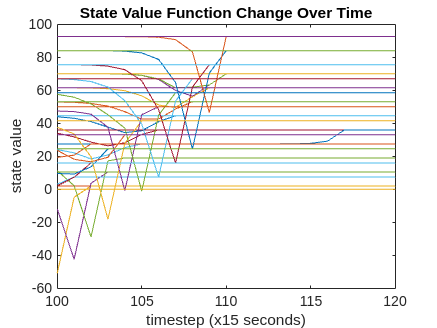

number_of_states = length(A(1,:,1));
state_value_over_time = zeros(length(time_index_vector),number_of_states);

for t = 1:length(time_index_vector)
    for state_index = 1:number_of_states
        state_value_over_time(t,state_index) = MDP.(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
    end
end

for state_index = 1:number_of_states
    plot(time_index_vector,state_value_over_time(:,state_index))
    hold on
end

hold off
title('State Value Function Change Over Time')
xlabel('timestep (x15 seconds)')
ylabel('state value')

start_time = 100;
start_state = 3;

% Run Simulation
[time_list, reward_list, state_list, state_value_list] = simulation_test(start_time,start_state,MDP,time_index_vector,destination_state);

simultion_result = [time_list, state_list, reward_list, state_value_list]

simultion_result =   100.0000    3.0000         0  -50.8000
  101.0000    3.0000  -50.0000   -4.8000
  102.0000    2.0000  -51.0000    2.0000
  103.0000    1.0000  -52.0000   10.5000
  104.0000   46.0000  -67.0000   33.0000
  105.0000   45.0000  -68.0000   41.5000
  106.0000   44.0000  -69.0000   50.0000
  107.0000   43.0000  -70.0000   58.5000
  108.0000   42.0000  -71.0000   67.0000
  109.0000   41.0000  -72.0000   75.5000
